clear;clc;
%close all;
folderPath = fullfile(pwd);

MData_bloch = load(fullfile(folderPath, ...
    '2504-fig5-Kernel1/100-1000-10-bloch-250428.mat'));
MData_RK4 = load(fullfile(folderPath, ...
    '2504-fig5-Kernel1/100-1000-10-RK4-250428.mat'));

M_bloch = MData_bloch.jlmrsData;
M_RK4 = MData_RK4.jlmrsData;

x = M_bloch.measure.qobs/0.02;
y0 = M_bloch.model.z_vec;
y = 0.5*(y0(1:end-1)+y0(2:end));
dz = abs(y0(2:end)-y0(1:end-1));
dz = repmat(dz,M_bloch.measure.Nq, 1);

bloch_Kernel = abs(M_bloch.kernel.kernel1D./dz)'*1e9;
RK4_Kernel = abs(M_RK4.kernel.kernel1D./dz)'*1e9;
Kernel_Loss = abs(bloch_Kernel-RK4_Kernel);
Kernel_RLoss = Kernel_Loss./RK4_Kernel;


set(gcf, 'Units', 'centimeters', 'Position', [0 0 8.4 12]);
subplot(4,4,1)
imagesc(x, y, bloch_Kernel)
set(gca, 'YDir', 'normal')
ylim([-50 0])
ylabel('Depth (m)')
title('kernel 1D (nV)')
set(gca, 'XTick', []);  
colorbar


subplot(4,4,2)
imagesc(x, y, RK4_Kernel)
set(gca, 'YDir', 'normal')
ylim([-50 0])
title('kernel 1D (nV)')
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colorbar

ax3 = subplot(4,4,3)

ax3 =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5422 0.7673 0.1566 0.1577]
            Units: 'normalized'

  显示 所有属性


imagesc(x, y, Kernel_Loss)
ylim([-50 0])
set(gca, 'YDir', 'normal')
title('Absolute Error (nV)')
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colormap(ax3, "sky")
colorbar

ax4 = subplot(4,4,4)

ax4 =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7484 0.7673 0.1566 0.1577]
            Units: 'normalized'

  显示 所有属性


imagesc(x, y, Kernel_RLoss*100)
ylim([-50 0])
set(gca, 'YDir', 'normal')
title('Relative Error (%)')
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colormap(ax4, flipud(colormap(ax4, "autumn")))
colorbar

MData_bloch1 = load(fullfile(folderPath, ...
    '2504-fig5-Kernel1/100-600-300-bloch-250428.mat'));
MData_RK41 = load(fullfile(folderPath, ...
    '2504-fig5-Kernel1/100-600-300-RK4-250428.mat'));

M_bloch1 = MData_bloch1.jlmrsData;
M_RK41 = MData_RK41.jlmrsData;

bloch_Kernel1 = abs(M_bloch1.kernel.kernel1D./dz)'*1e9;
RK4_Kernel1 = abs(M_RK41.kernel.kernel1D./dz)'*1e9;
Kernel_Loss1 = abs(bloch_Kernel1-RK4_Kernel1);
Kernel_RLoss1 = Kernel_Loss1./RK4_Kernel1;

subplot(4,4,5)
imagesc(x, y, bloch_Kernel1)
ylim([-50 0])
set(gca, 'YDir', 'normal')
ylabel('Depth (m)')
set(gca, 'XTick', []);
colorbar

subplot(4,4,6)
imagesc(x, y, RK4_Kernel1)
ylim([-50 0])
set(gca, 'YDir', 'normal')
set(gca, 'XTick', []); 
set(gca, 'YTick', []);
colorbar

ax7 = subplot(4,4,7)

ax7 =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5422 0.5482 0.1566 0.1577]
            Units: 'normalized'

  显示 所有属性


imagesc(x, y, Kernel_Loss1)
ylim([-50 0])
set(gca, 'YDir', 'normal')
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colormap(ax7, "sky")
colorbar

ax8 = subplot(4,4,8)

ax8 =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7484 0.5482 0.1566 0.1577]
            Units: 'normalized'

  显示 所有属性


imagesc(x, y, Kernel_RLoss1*100)
ylim([-50 0])
set(gca, 'YDir', 'normal')
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colormap(ax8, flipud(colormap(ax8, "autumn")))
colorbar

MData_bloch2 = load(fullfile(folderPath, ...
    '2504-fig5-Kernel1/200-600-300-bloch-250428.mat'));
MData_RK42 = load(fullfile(folderPath, ...
    '2504-fig5-Kernel1/200-600-300-RK4-250428.mat'));

M_bloch2 = MData_bloch2.jlmrsData;
M_RK42 = MData_RK42.jlmrsData;

bloch_Kernel2 = abs(M_bloch2.kernel.kernel1D./dz)'*1e9;
RK4_Kernel2 = abs(M_RK42.kernel.kernel1D./dz)'*1e9;
Kernel_Loss2 = abs(bloch_Kernel2-RK4_Kernel2);
Kernel_RLoss2 = Kernel_Loss2./RK4_Kernel2;

subplot(4,4,9)
imagesc(x, y, bloch_Kernel2)
ylim([-50 0])
set(gca, 'YDir', 'normal')
ylabel('Depth (m)')
set(gca, 'XTick', []);
colorbar

subplot(4,4,10)
imagesc(x, y, RK4_Kernel2)
ylim([-50 0])
set(gca, 'YDir', 'normal')
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colorbar

ax7 = subplot(4,4,11)

ax7 =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5422 0.3291 0.1566 0.1577]
            Units: 'normalized'

  显示 所有属性


imagesc(x, y, Kernel_Loss2)
ylim([-50 0])
set(gca, 'YDir', 'normal')
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colormap(ax7, "sky")
colorbar

ax8 = subplot(4,4,12)

ax8 =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7484 0.3291 0.1566 0.1577]
            Units: 'normalized'

  显示 所有属性


imagesc(x, y, Kernel_RLoss2*100)
ylim([-50 0])
set(gca, 'YDir', 'normal')
set(gca, 'XTick', []);
set(gca, 'YTick', []); 
colormap(ax8, flipud(colormap(ax8, "autumn")))
colorbar

MData_bloch3 = load(fullfile(folderPath, ...
    '2504-fig5-Kernel1/200-200-200-bloch-250428.mat'));
MData_RK43 = load(fullfile(folderPath, ...
    '2504-fig5-Kernel1/200-200-200-RK4-250428.mat'));

M_bloch3 = MData_bloch3.jlmrsData;
M_RK43 = MData_RK43.jlmrsData;

bloch_Kernel3 = abs(M_bloch3.kernel.kernel1D./dz)'*1e9;
RK4_Kernel3 = abs(M_RK43.kernel.kernel1D./dz)'*1e9;
Kernel_Loss3 = abs(bloch_Kernel3-RK4_Kernel3);
Kernel_RLoss3 = Kernel_Loss3./RK4_Kernel3;

subplot(4,4,13)
imagesc(x, y, bloch_Kernel3)
ylim([-50 0])
set(gca, 'YDir', 'normal')
xlabel('Pulse moement (As)')
ylabel('Depth (m)')
colorbar

subplot(4,4,14)
imagesc(x, y, RK4_Kernel3)
ylim([-50 0])
set(gca, 'YDir', 'normal')
xlabel('Pulse moement (As)')
set(gca, 'YTick', []);  
colorbar

ax3 = subplot(4,4,15)

ax3 =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5422 0.1100 0.1566 0.1577]
            Units: 'normalized'

  显示 所有属性


imagesc(x, y, Kernel_Loss3)
ylim([-50 0])
set(gca, 'YDir', 'normal')
xlabel('Pulse moement (As)')
set(gca, 'YTick', []);
colormap(ax3, "sky")
colorbar

ax4 = subplot(4,4,16)

ax4 =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7484 0.1100 0.1566 0.1577]
            Units: 'normalized'

  显示 所有属性


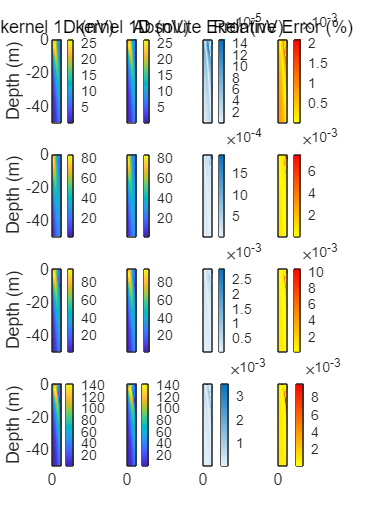

imagesc(x, y, Kernel_RLoss3*100)
ylim([-50 0])
set(gca, 'YDir', 'normal')
xlabel('Pulse moement (As)')
set(gca, 'YTick', []);  
colormap(ax4, flipud(colormap(ax4, "autumn")))
colorbar